# TNA010: Computer assignments 4

### Namn: Lovisa Svensson

### Datum: 2023-12-10

Kompletterad: 2023-12-12

## Problem 1

For this problem I loaded an adjacency graph and plotted centrality values, which determine how "central" a node is (which is to say, how many other nodes are connected to them).

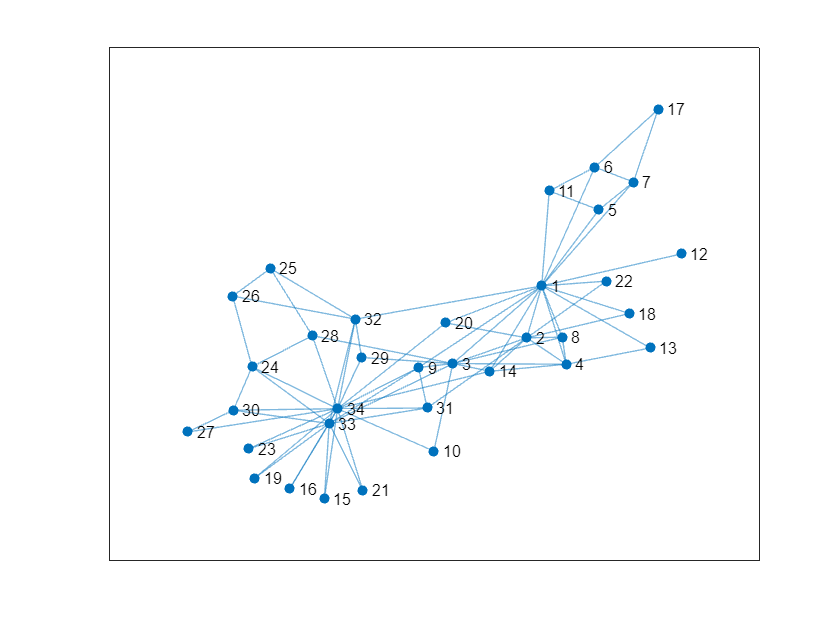

clear
clf

load('karate-club.mat')
A = Problem.A;

% a)
G = graph(A);
plot(G);

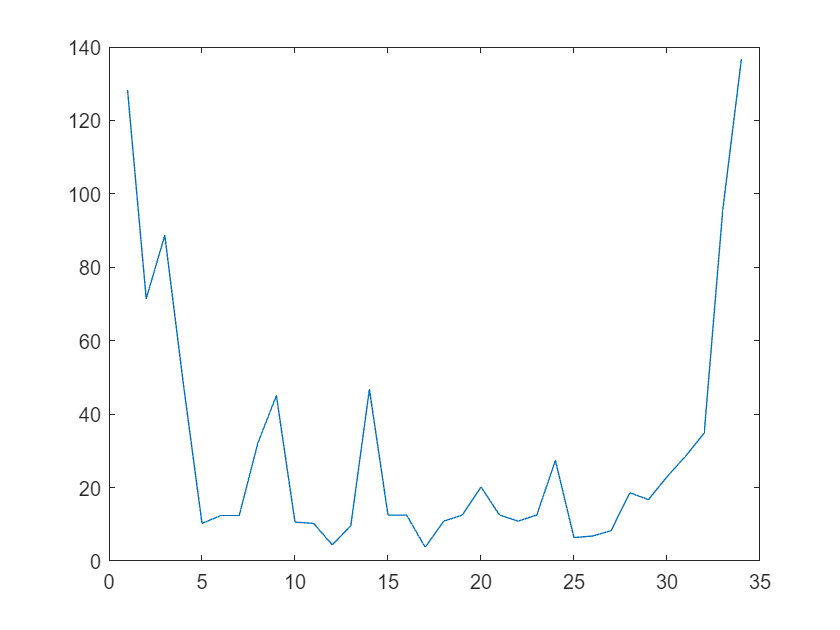

% b)
eA = expm(A);
plot(diag(eA))

% c) 

The most central nodes are node 34 and node 1. From the centrality plot they have the highest values, and this can also be seen in the graph as they have the highest amount of edges connected to them.

% d)

The next three nodes are: 3, 14, 9. It is not as apparent on first glance as the two most central nodes, but examining them closely show that they have a couple more edges than most other nodes.

## Problem 2

I computed the Fiedler vector and rearranged it in increasing order. The Fiedler vector is the corresponding eigenvector of the second smallest eigenvalue of the Laplacian matrix of A (using 10.3 in the book). It doesn't have the exact same values as in the book, but keeps the same "shape" at least.

% Compute the Laplacian matrix L
D = diag(sum(A));
L = D - A;

% Find the Fiedler vector
[V,D] = eigs(L,2,'smallestabs');

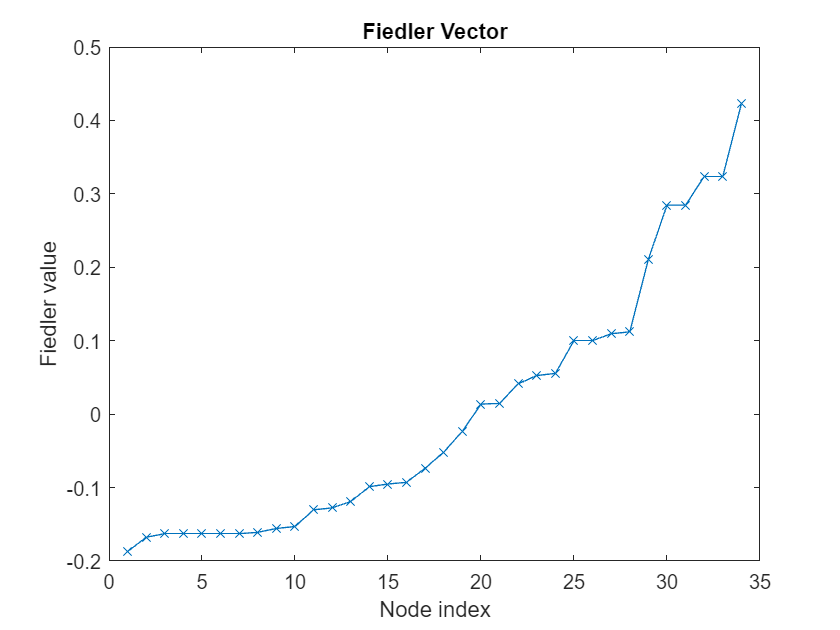

fiedler_vector = V(:,2);

% Plot the sorted Fiedler vector
figure;
plot(sort(fiedler_vector), 'x-');
title('Fiedler Vector');
xlabel('Node index');
ylabel('Fiedler value');

## Problem 3

For this problem I used the Spectral Partitioning guide on page 113 as a guide to compute the conductance. Eta defines the number of cut cases. This also doesn't have the exact same values but keeps the same shape as the figure.

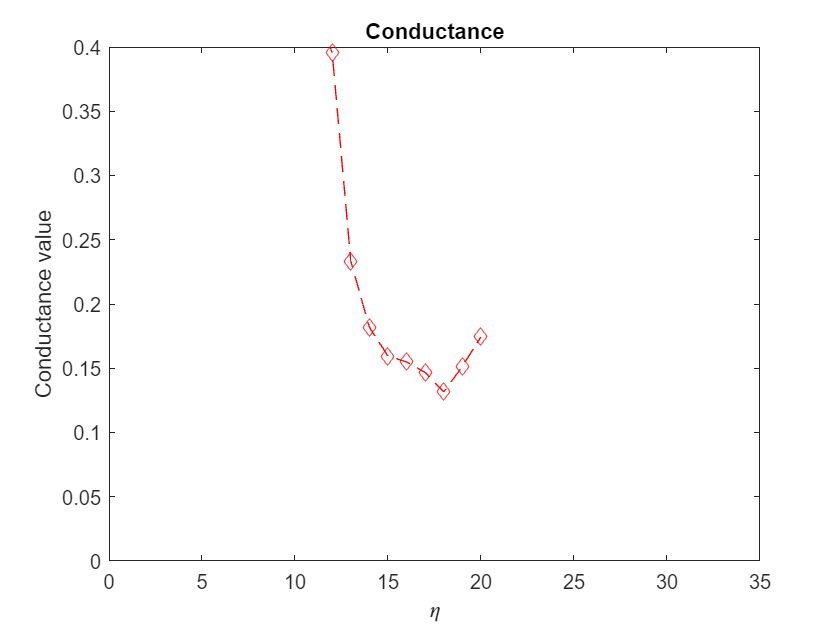

% The sorted Fiedler vector is a permutation
[~, P] = sort(fiedler_vector);

% Apply the permutation to the vertices of the graph
G_permuted = reordernodes(G, P);

% Need to make P into a column vector
P = P';

% Reordered adjacency matrix
% A_reordered = P * A * P' % not working?
A_reordered = adjacency(G_permuted);

% Reordered degree vector
e = ones(1, size(A_reordered, 2));
% d = A*e';
% d_reordered = P*d;
d_reordered = A_reordered * e';

eta_range = 10:20;
conductance_values = zeros(size(eta_range));
n = length(d_reordered);

% Caluclate conductance values
for i = 1:length(eta_range)
    eta = eta_range(i);
    n = length(d_reordered);

    conductance_values(i) = calculate_conductance(A_reordered, d_reordered, eta, n);
end

% Plot the conductance
figure;
plot(eta_range, conductance_values, '--diamondr');
title('Conductance');
xlabel('\eta');
ylabel('Conductance value');
xlim([0 35])
ylim([0 0.4])

function conductance_value = calculate_conductance(A, d, eta, n)
    numerator = 0;
    d_firstsum = 0;
    d_secondsum = 0;

    for i = 1:eta
        d_firstsum = d_firstsum + d(i);

        for j = eta+1:n
            % The numerator is the sum of all A vertices
            numerator = numerator + A(i,j);
        end
    end

    for j = eta+1:n
        d_secondsum = d_secondsum + d(j);
    end

    denominator = min(d_firstsum, d_secondsum);

    conductance_value = numerator/denominator;
end